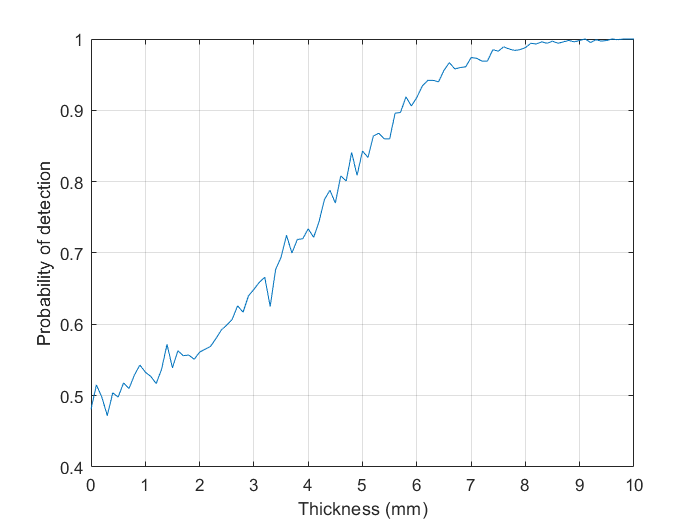

M = 5;
frequency = [4];
ks = 0;
variance = 0.02;
samples = 1000;
E_oil = 3;
E_air =1;
temp = 20;
salinity = 35;
theta = 0;
tmin = 0;
thickness_step = 0.1;
tmax= 10;
trials = 1000;


%% Probability plot
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
thickness = tmin:thickness_step:tmax;
probability = probability_of_detection(M, frequency, ks, thickness_step, variance, trials, E_oil, E_air, temp, salinity, theta, tmin, tmax);
plot(thickness, probability);
grid on;
xlabel("Thickness (mm)");
ylabel("Probability of detection");


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



R_oil = reflectivity(frequency, thickness, ks, E_oil, E_air, temp, salinity, theta);

E_water_prob = abs(E_water(temp, salinity, frequency));
R_water = ((sqrt(E_air) - sqrt(E_water_prob))/(sqrt(E_air) + sqrt(E_water_prob)))^2;
noise = sqrt(variance) * randn(length(frequency), length(R_oil));    
noisy_water = R_water + noise;


trials = 1000;
prob = double.empty;

tic
for i = tmin:thickness_step:tmax
    oil = 0;
    for j = 0:trials
        desired_reflectivity  = reflectivity(frequency, i, ks, E_oil, E_air, temp, salinity, theta);
        
        oil_found = Detection_probability(R_oil, M, frequency, ks, variance, E_air, temp, salinity, theta, tmin, tmax);
       
        if oil_found >= 1
            oil = oil + 1;
        end
    end
    
    prob(length(prob) + 1) = oil/trials;
    
end
toc
plot(thickness, prob);